# **Edges and Thinning**

## Import Photos and Acquire Dimensions

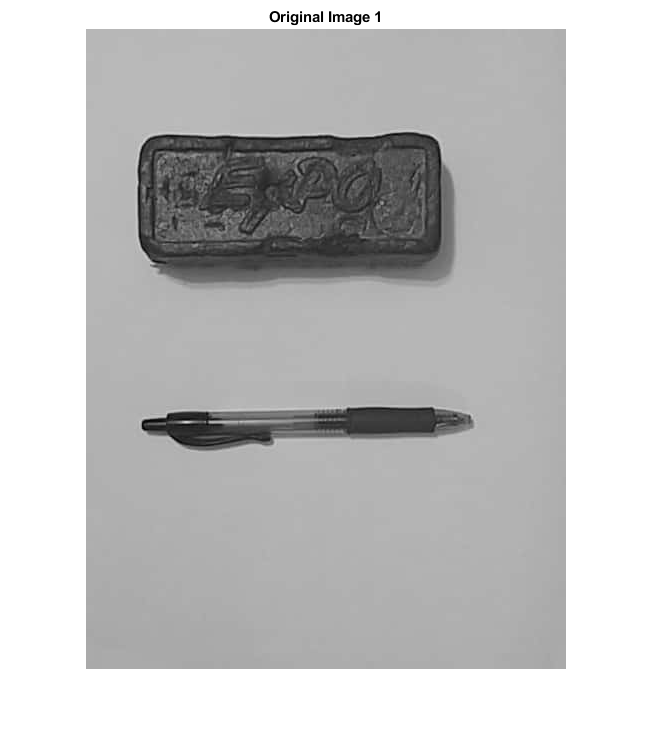

img1 = rgb2gray(imread('pic1.jpg'));
dim1 = size(img1);
H1 = dim1(1);
W1 = dim1(2);
figure
imshow(img1);
title("Original Image 1");

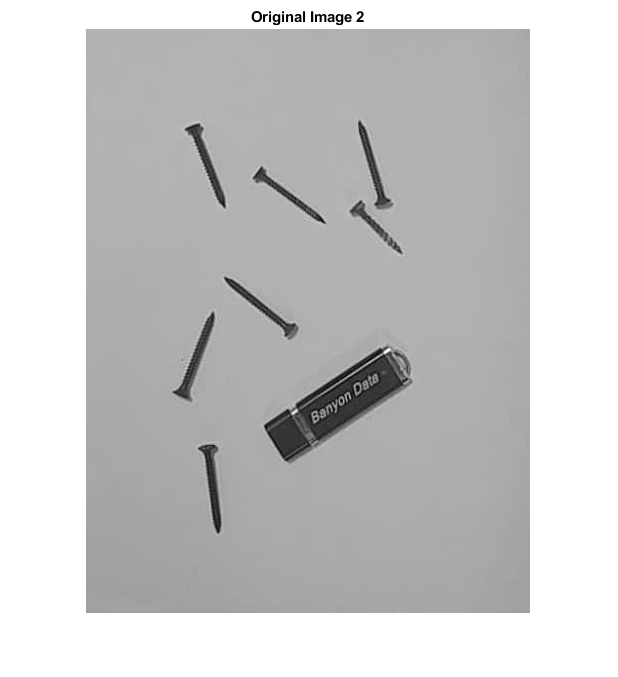


img2 = rgb2gray(imread('pic2.jpg'));
dim2 = size(img2);
H2 = dim2(1);
W2 = dim2(2);
figure
imshow(img2);
title("Original Image 2");

## Sobel Operator


$$\Delta_1 =\text{ }\left\lbrack \begin{array}{ccc}
-1 & 0\text{ } & 1\\
-2 & 0 & 2\\
-1 & 0 & 1
\end{array}\right\rbrack ,\Delta_2 =\left\lbrack \begin{array}{ccc}
1 & 2 & 1\\
0 & 0 & 0\\
-1 & -2 & -1
\end{array}\right\rbrack$$



$$\mathrm{Gradient}\text{ }\mathrm{Magnitude}=\sqrt{\Delta_1^2 +\Delta_2^2 }$$



$$\mathrm{Gradient}\text{ }\mathrm{Direction}=\mathrm{atan2}\left(\Delta_2 \text{ },\Delta_1 \right)$$


- Since these are 3x3 operators, we will need to pad the image by 1.

d1 = [-1 0 1; -2 0 2; -1 0 1];
d2 = [1 2 1; 0 0 0; -1 -2 -1];
pad = 1;

Image 1 Operation:

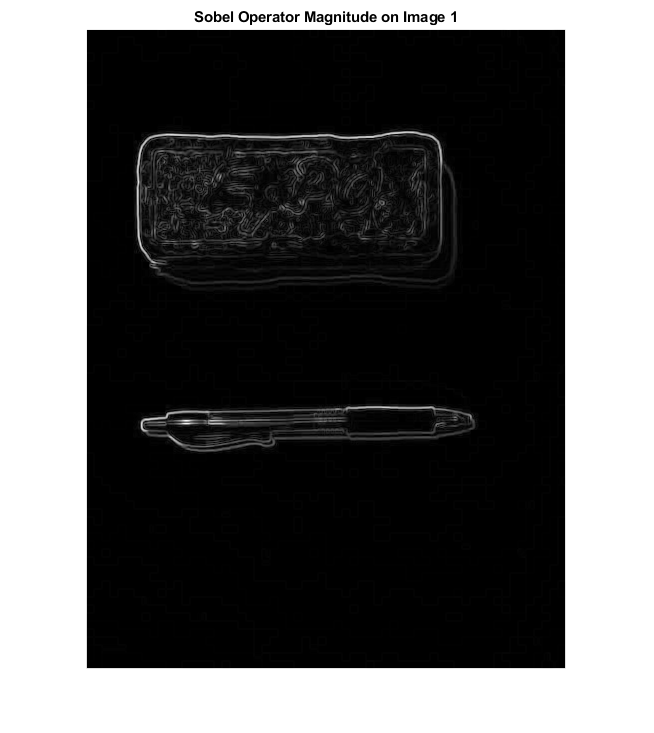

WorkingImg = double(padarray(img1, [pad,pad]));
Magnitude = zeros(size(img1));
Direction = zeros(size(img1));

for height = 1+pad:H1+pad

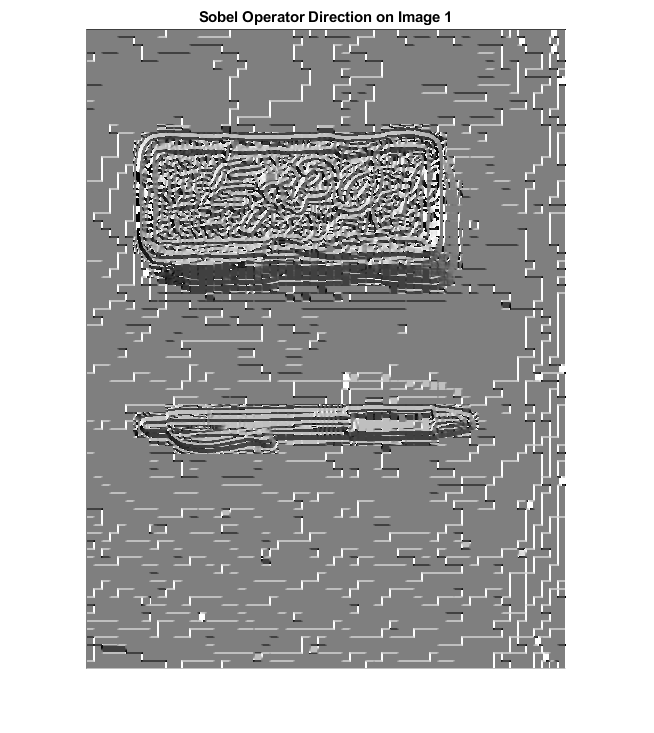

    for width = 1+pad:W1+pad
        d1_sum = 0;
        d2_sum = 0;
        for i = -pad:pad
            for j = -pad:pad
                d1_sum = d1_sum + WorkingImg(height + i, width + j) * d1(i+pad+1, j+pad+1);
                d2_sum = d2_sum + WorkingImg(height + i, width + j) * d2(i+pad+1, j+pad+1);
            end
        end
        Magnitude(height - pad, width - pad) = norm([d1_sum, d2_sum]);
        Direction(height - pad, width - pad) = atan2(d2_sum, d1_sum);
    end
end

img1Sobel = uint8(((255-0)/(max(Magnitude(:))-min(Magnitude(:))))*(Magnitude-min(Magnitude(:))));
Direction = uint8(((255-0)/(max(Direction(:))-min(Direction(:))))*(Direction-min(Direction(:))));

figure
imshow(img1Sobel);
title("Sobel Operator Magnitude on Image 1");

figure
imshow(Direction);
title("Sobel Operator Direction on Image 1");

Image 2 Operation:

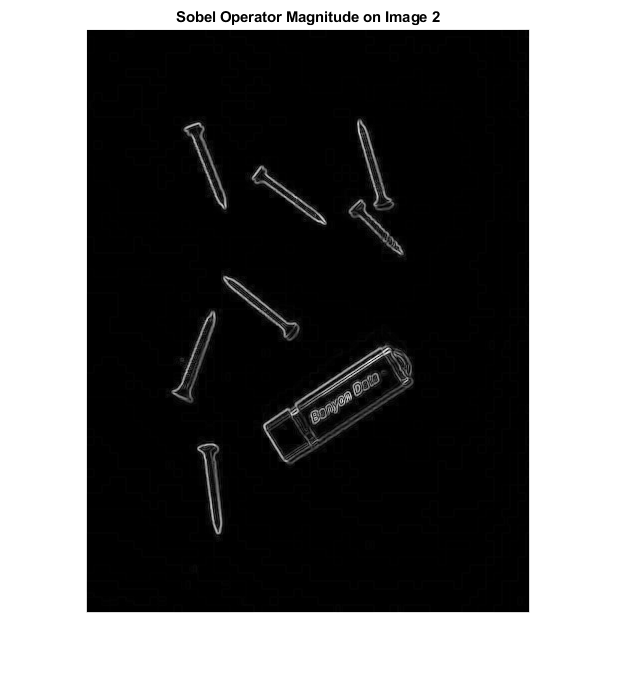

WorkingImg = double(padarray(img2, [pad,pad]));
Magnitude = zeros(size(img2));
Direction = zeros(size(img2));

for height = 1+pad:H2+pad
    for width = 1+pad:W2+pad
        d1_sum = 0;
        d2_sum = 0;
        for i = -pad:pad
            for j = -pad:pad
                d1_sum = d1_sum + WorkingImg(height + i, width + j) * d1(i+pad+1, j+pad+1);
                d2_sum = d2_sum + WorkingImg(height + i, width + j) * d2(i+pad+1, j+pad+1);
            end
        end
        Magnitude(height - pad, width - pad) = norm([d1_sum, d2_sum]);
        Direction(height - pad, width - pad) = atan2(d2_sum, d1_sum);
    end
end

img2Sobel = uint8(((255-0)/(max(Magnitude(:))-min(Magnitude(:))))*(Magnitude-min(Magnitude(:))));
Direction = uint8(((255-0)/(max(Direction(:))-min(Direction(:))))*(Direction-min(Direction(:))));

figure
imshow(img2Sobel);
title("Sobel Operator Magnitude on Image 2");

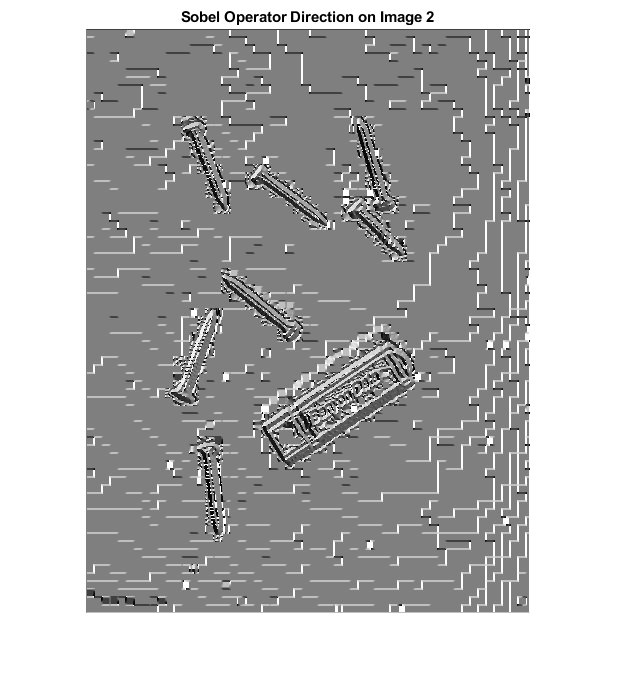


figure
imshow(Direction);
title("Sobel Operator Direction on Image 2");

## Roberts Operator


$$\Delta_1 =\left\lbrack \begin{array}{cc}
0 & 1\\
-1 & 0
\end{array}\right\rbrack ,\Delta_2 =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -1
\end{array}\right\rbrack$$



$$\mathrm{Gradient}\text{ }\mathrm{Magnitude}=\sqrt{\Delta_1^2 +\Delta_2^2 }$$



$$\mathrm{Gradient}\text{ }\mathrm{Direction}=\mathrm{atan2}\left(\Delta_2 \text{ },\Delta_1 \right)$$


- Since these are 2x2 operators, we will need to pad the image by 1 on the right and bottom edges.

- Note that the 0's in the padding will have a larger affect when using these kernels because they are small in dimension.

d1 = [0 1; -1 0];
d2 = [1 0; 0 -1];
pad = 1;

Image 1 Operation:

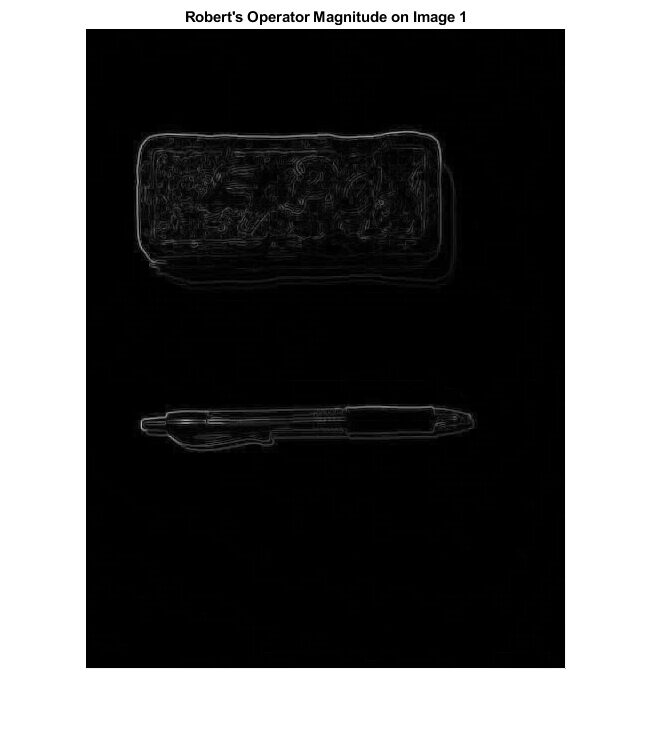

WorkingImg = double(padarray(img1, [pad,pad], 'post'));
Magnitude = zeros(size(img1));
Direction = zeros(size(img1));

for height = 1:H1
    for width = 1:W1
        d1_sum = 0;
        d2_sum = 0;
        for i = 0:pad
            for j = 0:pad
                d1_sum = d1_sum + WorkingImg(height + i, width + j) * d1(i+pad, j+pad);
                d2_sum = d2_sum + WorkingImg(height + i, width + j) * d2(i+pad, j+pad);
            end
        end
        Magnitude(height, width) = norm([d1_sum, d2_sum]);
        Direction(height, width) = atan2(d2_sum, d1_sum);
    end
end

img1Roberts = uint8(((255-0)/(max(Magnitude(:))-min(Magnitude(:))))*(Magnitude-min(Magnitude(:))));
Direction = uint8(((255-0)/(max(Direction(:))-min(Direction(:))))*(Direction-min(Direction(:))));

figure
imshow(img1Roberts);
title("Robert's Operator Magnitude on Image 1");

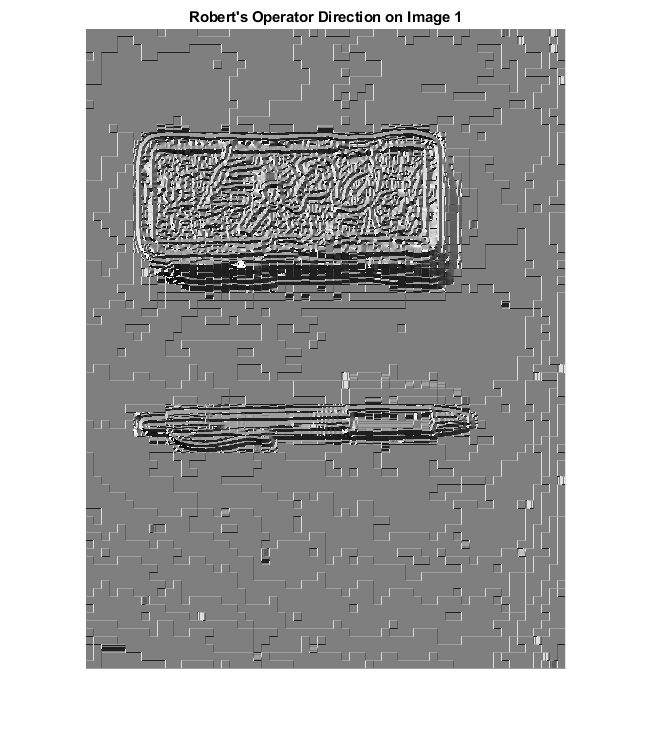


figure
imshow(Direction);
title("Robert's Operator Direction on Image 1");

Image 2 Operation:

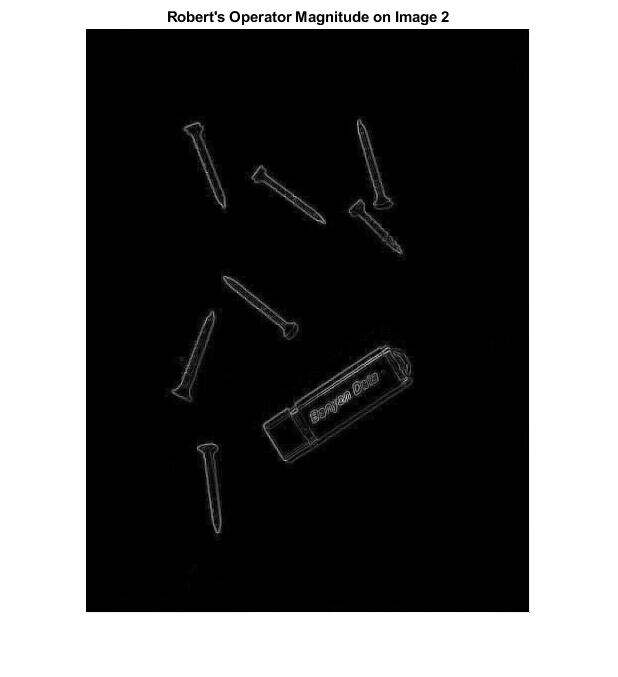

WorkingImg = double(padarray(img2, [pad,pad], 'post'));
Magnitude = zeros(size(img2));
Direction = zeros(size(img2));

for height = 1:H2
    for width = 1:W2
        d1_sum = 0;
        d2_sum = 0;
        for i = 0:pad
            for j = 0:pad
                d1_sum = d1_sum + WorkingImg(height + i, width + j) * d1(i+pad, j+pad);
                d2_sum = d2_sum + WorkingImg(height + i, width + j) * d2(i+pad, j+pad);
            end
        end
        Magnitude(height, width) = norm([d1_sum, d2_sum]);
        Direction(height, width) = atan2(d2_sum, d1_sum);
    end
end

img2Roberts = uint8(((255-0)/(max(Magnitude(:))-min(Magnitude(:))))*(Magnitude-min(Magnitude(:))));
Direction = uint8(((255-0)/(max(Direction(:))-min(Direction(:))))*(Direction-min(Direction(:))));

figure
imshow(img2Roberts);
title("Robert's Operator Magnitude on Image 2");

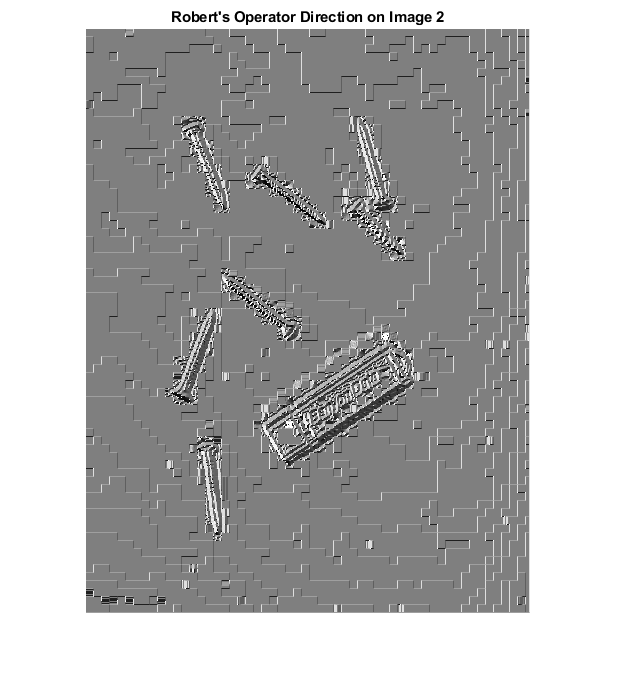


figure
imshow(Direction);
title("Robert's Operator Direction on Image 2");

## Thresholding

- The thresholding operations will be performed on the resulting 2 magnitude images when using the Sobel operator: *img1Sobel *and *img2Sobel.*

- Determining the threshold value will be done via the Otsu method that is used by the *graythresh()* function in MATLAB.

- Since *graythresh()* returns a double value from 0 to 1, it needs to be normalized back to the range of 0 to 255.

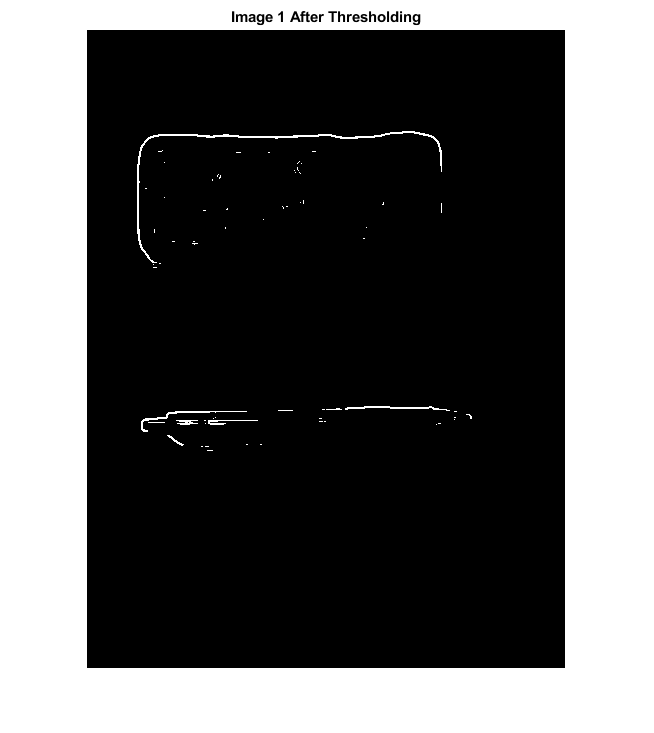

img1Thresh = uint8(255 * graythresh(img1Sobel));
img1BW = uint8(255 * (img1Sobel > img1Thresh));

figure
imshow(img1BW);
title("Image 1 After Thresholding")

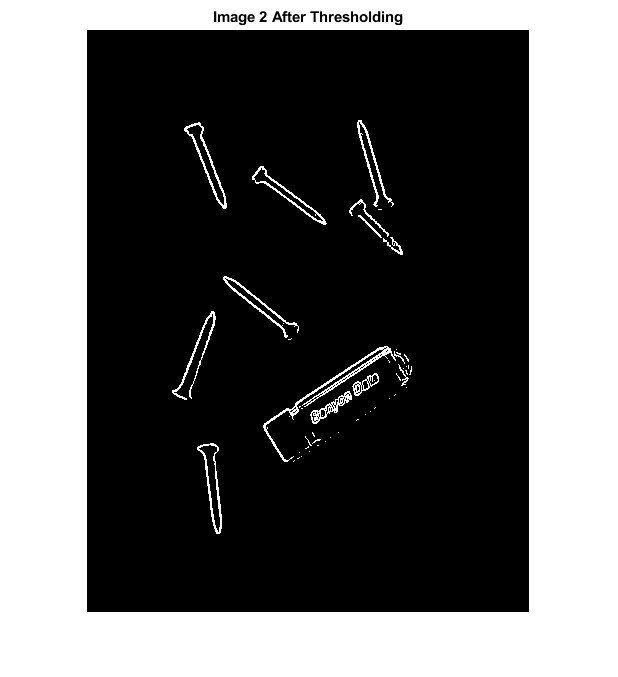


img2Thresh = uint8(255 * graythresh(img2Sobel));
img2BW = uint8(255 * (img2Sobel > img2Thresh));

figure
imshow(img2BW);
title("Image 2 After Thresholding")

## Thinning

- The thinning operations will be performed on the resulting 2 images from the thresholding section.

- Using Zhang-Suen Thinning Algorithm.

- The auxilary function findConnectivity.m is used to find the connectivity number for a given 3x3 window.

Image 1 Operation:

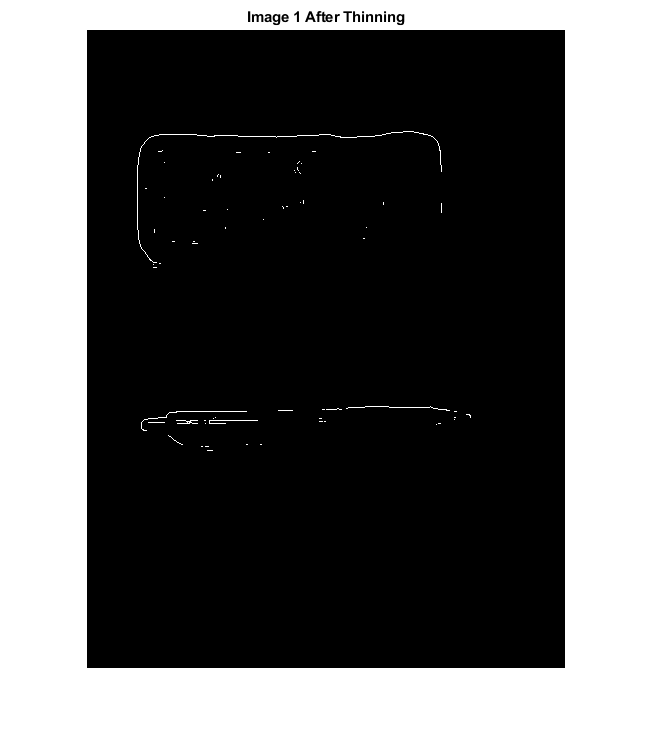

changeFlag = 1;
changeMat = ones(size(img1BW));
thin1 = logical(img1BW);

while changeFlag
    changeFlag = 0;
    
    % Step 1:
    for i = 2:H1-1
        for j = 2:W1-1
            window = thin1(i-1:i+1, j-1:j+1);
            % number of neighbors that are 1:
            neighborNum = sum(sum(window)) - window(2,2);
            % get connectivity:
            ConnectivityNum = findConnectivity(window);
            
            cond0 = (window(2,2) == 1);
            cond1 = (ConnectivityNum == 1);
            cond2 = (neighborNum >= 2 && neighborNum <= 6);
            cond3 = (window(1,2) * window(2,3) * window(3,2) == 0);
            cond4 = (window(2,3) * window(3,2) * window(2,1) == 0);
            
            if (cond0 && cond1 && cond2 && cond3 && cond4)
                changeMat(i,j)=0;
                changeFlag = 1;
            end
        end
    end
    thin1 = thin1 .* changeMat;
    % Step 2:
    for i = 2:H1-1
        for j = 2:W1-1             
            window = thin1(i-1:i+1, j-1:j+1);
            % number of neighbors that are 1:
            neighborNum = sum(sum(window)) - window(2,2);
            % get connectivity:
            ConnectivityNum = findConnectivity(window);    
            
            cond0 = (window(2,2) == 1);
            cond1 = (ConnectivityNum == 1);
            cond2 = (neighborNum >= 2 && neighborNum <= 6);
            cond3 = (window(1,2) * window(2,3) * window(2,1) == 0);
            cond4 = (window(1,2) * window(3,2) * window(2,1) == 0);
            
            if (cond0 && cond1 && cond2 && cond3 && cond4)
                changeMat(i,j)=0;
                changeFlag = 1;
            end
        end
    end
    thin1 = thin1 .* changeMat;
end

figure
imshow(thin1)
title("Image 1 After Thinning")

Image 2 Operation:

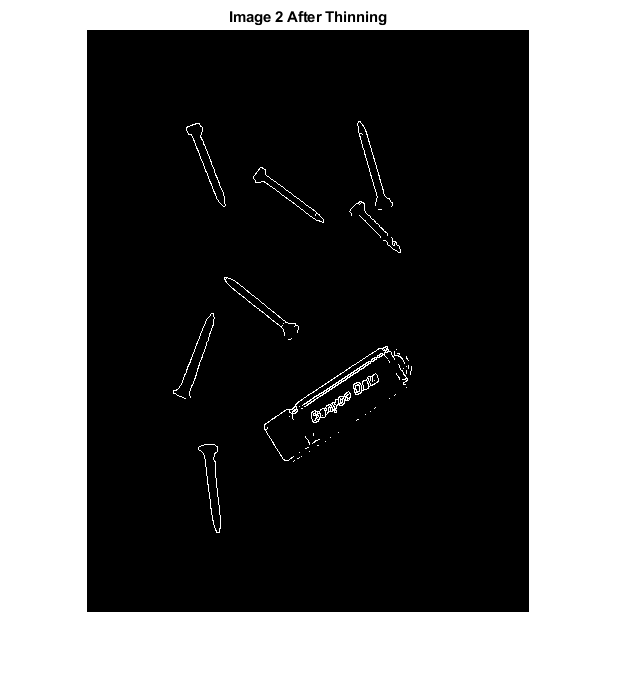

changeFlag = 1;
changeMat = ones(size(img2BW));
thin2 = logical(img2BW);

while changeFlag
    changeFlag = 0;
    
    % Step 1:
    for i = 2:H2-1
        for j = 2:W2-1
            window = thin2(i-1:i+1, j-1:j+1);
            % number of neighbors that are 1:
            neighborNum = sum(sum(window)) - window(2,2);
            % get connectivity:
            ConnectivityNum = findConnectivity(window);
            
            cond0 = (window(2,2) == 1);
            cond1 = (ConnectivityNum == 1);
            cond2 = (neighborNum >= 2 && neighborNum <= 6);
            cond3 = (window(1,2) * window(2,3) * window(3,2) == 0);
            cond4 = (window(2,3) * window(3,2) * window(2,1) == 0);
            
            if (cond0 && cond1 && cond2 && cond3 && cond4)
                changeMat(i,j)=0;
                changeFlag = 1;
            end
        end
    end
    thin2 = thin2 .* changeMat;
    % Step 2:
    for i = 2:H2-1
        for j = 2:W2-1             
            window = thin2(i-1:i+1, j-1:j+1);
            % number of neighbors that are 1:
            neighborNum = sum(sum(window)) - window(2,2);
            % get connectivity:
            ConnectivityNum = findConnectivity(window);    
            
            cond0 = (window(2,2) == 1);
            cond1 = (ConnectivityNum == 1);
            cond2 = (neighborNum >= 2 && neighborNum <= 6);
            cond3 = (window(1,2) * window(2,3) * window(2,1) == 0);
            cond4 = (window(1,2) * window(3,2) * window(2,1) == 0);
            
            if (cond0 && cond1 && cond2 && cond3 && cond4)
                changeMat(i,j)=0;
                changeFlag = 1;
            end
        end
    end
    thin2 = thin2 .* changeMat;
end

figure
imshow(thin2)
title("Image 2 After Thinning")

## Discussion

When detecting the edges of grayscale images, I found that I prefer the results of the Sobel operator over the Robert's operator. The magnitude response of the Sobel operator yielded much cleaner and more defined results outlining the edges of objects, whereas the Robert's operator produced a slightly noisier image that did not have a large contrast between edge and non-edge pixels. I suspect that this is due to the Robert's operator not using all the information surrounding each pixel. Furthermore, it produces a duller image because any surrounding pixel value within the filter is never scaled by more than 1. In contrast, the Sobel operator uses all neighboring pixels to weight the likelihood of either a vertical or horizontal contrast change. Additionally, the Sobel operator scales direct contrast change to a neighboring pixel in the N, E, S, W, by 2 instead of one, producing sharper edges. When examining the direction vector image between the two operators, it seems that the Sobel operator produced a slightly smoother and more uniform result. I would guess that since the Sobel filter has more overlap with filters on surrounding pixels, it produces a smoother and more gradually changing gradient.

To accomplish thresholding, I used MATLAB's built in function *graythresh()* to find the optimal threshold value for each grayscale image. This function uses Otsu's Method behind the scenes. The threshold on image 1 did not capture very much detail, but did offer some prominant lines that were useful in examining results in the thinning stage; therefore this threshold value was not altered. The use of Otsu's method on image 2 was more than sufficient at capturing the right lines and pixels while masking out unnecessary ones.

The thinning algorithm I chose to implement was the Zhang-Suen Algorithm. The results on both images from the process yielded objects that maintained shape, pixel connectivity, and scale. I discovered no serious loss of information. However, I conclude that image 2 may have benefited from an expansion process before applying thinning. Expansion would help in connecting areas with small gaps and preventing the thinning algorithm from creating larger gaps or deformations in the image objects. With an expansion, many of the gaps around the head of each nail would have been filled and therefore not made even more pronounced by the thinning algorithm. Additionally, it would preserve the shape of some objects as well; this can be observed near the head of the bottom nail. There is a noticable indent on the right side which is accentuated by the thinning algorithm. Again, the use of an expansion would have made that area of the object more uniform and therefore less deformed by thinning.